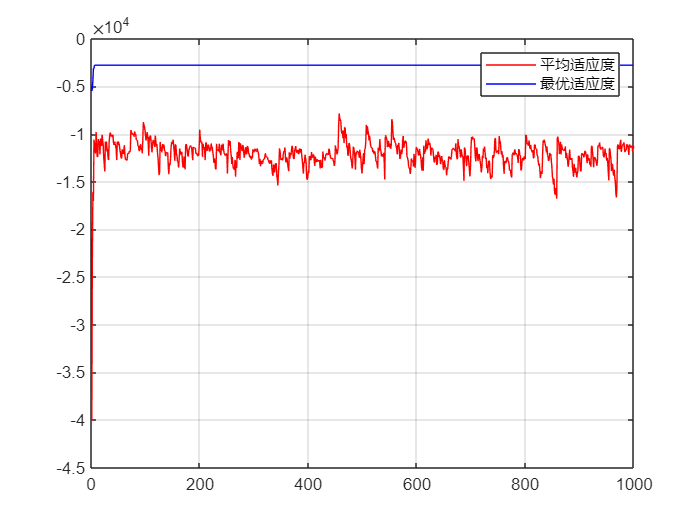

x'axaclc;
clear;
%% 基础参数
popSize = 200;  %种群内个体数目
N_chrom = 30; %染色体节点数，也就是每个个体有多少条染色体，其实说白了就是看适应函数里有几个自变量。
iter = 1000; %迭代次数，也就是一共有多少代
C = [3200 2800 2800 2900 0;3200 3400 3900 2880 0;20500 26000 31000 0 0;3200 3600 4100 2680 0;870 1500 1800 0 0;1850 1900 2070 1900 1650];     % 成本
W = [0.141; 0.195; 0.139; 0.188; 0.151; 0.195];     % 权重
S = [1 0 0 0 0;1 1 0.556 0.0462 0;0.438 1 0.75 0 0;1 1 0.938 0.36 0;0.319 1 0.75 0 0;1 1 0.969 1 0.438];     % 模块隶属度
g = [1 1 0 0 0;0 0 1 0 0;0 0 0 1 0;0 1 0 0 1;0 0 0 1 0;1 0 1 0 0];
mut = 0.2;  %突变概率
acr = 0.2; %交叉概率
N = 6;                      % 行数
M = 5;                      % 列数
best = 1;
chrom_range = [-10 10];%每个节点的值的区间
fitness_ave = zeros(1, iter);%存放每一代的平均适应度
fitness_best = zeros(1, iter);%存放每一代的最优适应度
% 初始化，这只是用于生成第一代个体，并计算其适应度函数
chrom = Initialize(popSize, N,M); %初始化染色体
fitness = CalFitness(chrom, popSize, M, N, W, S, g, C); %计算适应度
chrom_best = FindBest(chrom, fitness, N_chrom); %寻找最优染色体
fitness_best(1) = chrom_best(end); %将当前最优存入矩阵当中
fitness_ave(1) = CalAveFitness(fitness); %将当前平均适应度存入矩阵当中
%% 用于生成以下其余各代，一共迭代多少步就一共有多少代
for t = 2:iter
    chrom = MutChrom(chrom, mut, popSize, N_chrom); %变异
    chrom = AcrChrom(chrom, acr, popSize, N_chrom); %交叉
    fitness = CalFitness(chrom, popSize, M, N, W, S, g, C); %计算适应度
    chrom_best_temp = FindBest(chrom, fitness, N_chrom); %寻找最优染色体
    if chrom_best_temp(end)>chrom_best(end) %替换掉当前储存的最优
        chrom_best = chrom_best_temp;
    end
    %%替换掉最劣
    [chrom, fitness] = ReplaceWorse(chrom, chrom_best, fitness);
    fitness_best(t) = chrom_best(end); %将当前最优存入矩阵当中
    fitness_ave(t) = CalAveFitness(fitness); %将当前平均适应度存入矩阵当中
end
%% 作图
figure(1)
plot(1:iter, fitness_ave, 'r', 1:iter, fitness_best, 'b')
grid on
legend('平均适应度', '最优适应度')

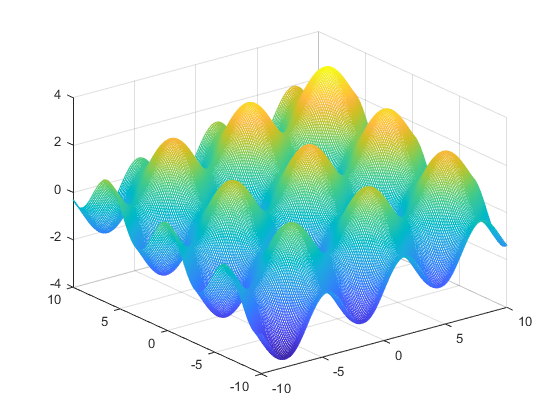

suoe=PlotModel(chrom_best);

%% 输出结果
disp(['最优染色体为', num2str(chrom_best(1:end-1))])

最优染色体为0  0  0  0  1  0  0  0  0  1  0  0  0  1  0  0  0  0  0  1  0  0  0  0  1  1  0  0  0  0


mybest = reshape(chrom_best(1:end-1), 5, 6)'

mybest =      0     0     0     0     1
     0     0     0     0     1
     0     0     0     1     0
     0     0     0     0     1
     0     0     0     0     1
     1     0     0     0     0


disp(['最优适应度为', num2str(chrom_best(end))])

最优适应度为-2774.8946


function chrom_new = Initialize(popSize, N, M)
    % 初始化染色体，随机生成popSize个个体，每个染色体有N_chrom个节点
    chrom_new = round(rand(popSize, N*M));
    for i = 1:popSize
        for j =1:N
            idx = randperm(M, 1); % 生成一个随机索引
            chrom_new(i, (j-1)*M+1 :j*M) = 0; % 将当前行全部设为0
            chrom_new(i, (j-1)*M+idx) = 1; % 在随机位置设置为1
        end
    end
end

Initialize这个函数生成一个具有随机值的初始染色体矩阵，每个染色体的值都在指定的范围内。

function fitness = CalFitness(pop, popSize, M, N, W, S, g, C)
    % 计算适应度的函数
    fitness = zeros(popSize, 1);

    % 计算每个个体的适应度
    for i = 1:popSize
        k = reshape(pop(i,:), M, N)'; % 将染色体reshape为矩阵
        cost_constraint = (1 + 0.5) * sum(C .* k, 'all'); % 计算成本约束

        % 使用给定公式计算适应度
        fitness(i) = 1000 * sum(W .* sum(S .* k .* g, 2), 'all') / sum(sum(C .* k .* g, 2), 'all') - cost_constraint;
    end
end

function chrom_best = FindBest(chrom, fitness, N_chrom)
    % 寻找适应度最高的染色体
    chrom_best = zeros(1, N_chrom+1);
    [maxNum, maxCorr] = max(fitness);
    chrom_best(1:N_chrom) = chrom(maxCorr, :);
    chrom_best(end) = maxNum;
end

这个函数用于在给定染色体矩阵和适应度矩阵的情况下，找到适应度最高的染色体。

%% 用于对每代共100个个体进行变异处理
function chrom_new = MutChrom(chrom, mut, popSize, N_chrom)
    % 对每个个体进行变异处理
    for i = 1:popSize
        mut_rand = rand; % 随机生成一个数，代表基因突变的概率
        if mut_rand <= mut
            % 如果基因突变概率小于等于阈值，则进行基因突变处理
            row_to_mutate = randi(N_chrom); % 随机选择一行进行变异
            new_row = chrom(i, :); 
            new_row(floor((row_to_mutate-1) / 5)* 5+1:floor((row_to_mutate-1)  / 5) * 5+5) = 0; 
            new_row(row_to_mutate) = 1;
            % 将所选行替换为新的只有一个1的行
            chrom(i, :) = new_row;
        end
    end
    chrom_new = chrom;
end

这个函数用于对每个个体进行变异处理。对于每个个体，根据给定的变异概率（`mut`），以及随机生成的数值，决定是否进行基因突变。

function chrom_new = AcrChrom(chrom, acr, popSize, N_chrom)
    % 对每个个体进行交叉处理
    for i = 2:popSize
        acr_rand = rand; % 随机生成一个数，代表个体是否进行交叉处理的概率
        if acr_rand < acr
            row_to_acr = randi(5); % 随机选择交叉点
            mask1 = [ones(1, row_to_acr*5), zeros(1, N_chrom - row_to_acr*5)];
            mask2 = not(mask1);
            f_row = chrom(i,:);%父亲染色体
            m_row= chrom(i-1,:);%母亲染色体
            new_row = mask1.*f_row+mask2.*m_row;
            % 将所选行替换为新的只有一个1的行
            chrom(i, :) = new_row;
        end
    end
    chrom_new = chrom;
end


这个函数用于对每个个体进行交叉处理。对于每个个体，根据给定的交叉概率（`acr`），以及随机生成的数值，决定是否进行交叉处理。

function [chrom_new, fitness_new] = ReplaceWorse(chrom, chrom_best, fitness)
    % 替换适应度较差的个体
    max_num = max(fitness);
    min_num = min(fitness);
    limit = (max_num - min_num) * 0.2 + min_num;

    replace_corr = fitness < limit;

    replace_num = sum(replace_corr);
    chrom(replace_corr, :) = ones(replace_num, 1) * chrom_best(1:end-1);
    fitness(replace_corr) = ones(replace_num, 1) * chrom_best(end);
    chrom_new = chrom;
    fitness_new = fitness;
end

这个函数用于替换适应度较差的个体。根据设定的阈值（`limit`），将适应度低于阈值的个体替换为当前最优个体。

function fitness_ave = CalAveFitness(fitness)
    % 计算平均适应度
    fitness_ave = nanmean(fitness);
end

这个函数用于计算给定适应度矩阵的平均适应度。

function y = PlotModel(chrom)
    % 绘制模型
    x = chrom(1);
    y = chrom(2);
    z = chrom(3);
    figure(2)
    scatter3(x, y, z, 'ko')
    hold on
    [X, Y] = meshgrid(-10:0.1:10);
    Z = sin(X) + cos(Y) + 0.1 * X + 0.1 * Y;
    mesh(X, Y, Z)
    y = 1;
end


这个函数用于绘制模型。它接受一个染色体作为输入，并在三维坐标中绘制染色体的位置，同时绘制一个函数表面。在这个问题中，函数表面的形式是 `sin(X) + cos(Y) + 0.1 * X + 0.1 * Y`。